# UWB Localization Using IEEE 802.15.4z

This example shows how to estimate the location of a single device as per the IEEE® 802.15.4z™ standard, using the Communications Toolbox™.

## Overview

The IEEE 802.15.4z amendment of the IEEE® 802.15.4 standard is a MAC and PHY specification designed for ranging and localization using ultra wideband (UWB) communication.

The key ranging and localization functionality of the 802.15.4z amendment includes 3 MAC-level techniques:

- Single-sided two-way ranging (SS-TWR) - One device estimates the distance between two devices by using frame transmission in both directions of a wireless 802.15.4z link. This technique is demonstrated in the UWB Ranging using IEEE 802.15.4z example.

- Double-sided two-way ranging (DS-TWR) - Both devices estimate the distance between the two devices by using frame transmission in both directions of a wireless 802.15.4z link.

- One-way ranging / time-difference of arrival (OWR/TDOA) - Network-assisted localization whereby one device communicates with a set of synchronized nodes to estimate the position of the device.

This example demonstrates the OWR/TDOA technique for uplink transmissions, by using MAC and PHY frames are compatible with the IEEE 802.15.4 standard and the IEEE 802.15.4z amendment

## One-Way Ranging / Time-Difference of Arrival (OWR/TDOA)

One-way ranging (OWR) involves frame transmission either in the uplink or in the downlink direction. In the uplink case, the device to be localized periodically broadcasts short messages referred to as *blinks*. The IEEE 802.15.4z amendment does not stipulate a specific frame format for the blinks, however it states that blinks should be as short as possible. These blink messages are received by a set of infrastructure nodes that are synchronized either through a wired backbone or via an UWB wireless communications link. In the downlink case, the synchronized nodes periodically transmit broadcast messages with a known time offset.

The time-difference of arrival (TDOA) between the periodic messages places the device in one hyperbolic surface for each pair of synchronized nodes. The intersection of all hyperbolic surfaces (for every pair of synchronized nodes) gives the location estimate for the device.

This example demonstrates the uplink OWR case. 

## Setup

#### Configure Network

Set up a network with 3 synchronized nodes and 1 device, in a 100x100 plane:

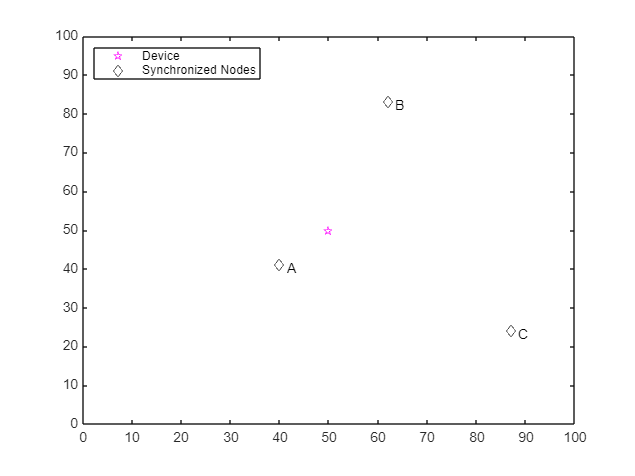

numNodes = 3;
deviceLoc = [50 50];  % place device at the center
nodeLoc = [40 41;
           62 83;
           87 24];
TDOA = nan(numNodes);
helperShowLocations(deviceLoc,nodeLoc);

Calculate the actual distance and time of flight (TOF) between nodes and the device.

actualDistances = sqrt(sum((nodeLoc - deviceLoc).^2, 2));
c = physconst('LightSpeed'); % speed of light (m/s)
actualTOF = actualDistances/c;

SNR = 30;  % in dB sound to noise ratio

#### Configure Blinks

Use a short (IEEE 802.15.4 MAC) data frame as a blink.

numBlinks = 1;

% MAC layer:
payload = '00'; 
cfg = lrwpan.MACFrameConfig( ...
        FrameType='Data', ...
        SourceAddressing='Short address', ...
        SourcePANIdentifier='AB12', ...
        SourceAddress='CD77');
blinkMAC = lrwpan.MACFrameGenerator(cfg,payload);

% PHY layer:
% Ensure the Ranging field is enabled. 
% Also set the proper PSDU length.
blinkPHYConfig = lrwpanHRPConfig( ...
    Mode='HPRF', ...
    STSPacketConfiguration=1, ...
    PSDULength=length(blinkMAC)/8, ...
    Ranging=true);
blinkPHY = lrwpanWaveformGenerator( ...
    blinkMAC, ...
    blinkPHYConfig);

% Cache preamble, to use in preamble detection. 
% Get the 1st instance out of the Nsync=PreambleDuration repetitions.
indices = lrwpanHRPFieldIndices(blinkPHYConfig); % length (start/end) of each field
blinkPreamble = blinkPHY( ...
    1:indices.SYNC(end)/blinkPHYConfig.PreambleDuration); % 1 of the Nsync repetitions

## Run Simulation

In the simulation loop, a blink propagates to each node with a propagation delay that is determined by their distinct distance. Next, each pair of nodes calculates the difference of their blink arrival times. As a result, the position of the device is estimated within a hyperbolic surface for each pair of nodes. The intersection of all surfaces gives the position estimate for the device. Here, a plot of 2D curves shows the intersection point to indicate the position estimate for the device.

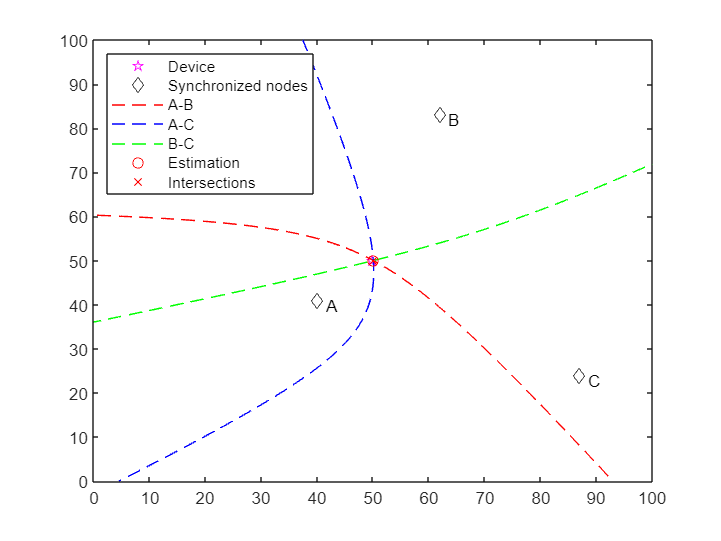

vfd = dsp.VariableFractionalDelay;
arrivalTime = zeros(1,numNodes);

plotStr = {'r--','b--','g--'};
[x, y] = deal(cell(1, 3));

for idx = 1:numBlinks
  for node = 1:numNodes
    % Transmission and reception of blink
    % Each node receives a specifically delayed version of the blink
    tof = actualTOF(node);
    samplesToDelay = tof * blinkPHYConfig.SampleRate;
    reset(vfd);
    release(vfd);
    vfd.MaximumDelay = ceil(1.1*samplesToDelay);
    delayedBlink = vfd( ...
        [blinkPHY; zeros(ceil(samplesToDelay), 1)], ...
        samplesToDelay);

    % Add white Gaussian noise
    receivedBlink = awgn(delayedBlink,SNR);

    % Node receiver detection of preamble
    preamPos = helperFindFirstHRPPreamble( ...
        receivedBlink,blinkPreamble,blinkPHYConfig);
 
    % Transmit each blink at t=0 of each period. The blink arrives
    % at different instances at each node, due to their dissimilar
    % distance to the device.
    arrivalTime(node) = ( ...
        preamPos - indices.SYNC(end) / ...
        blinkPHYConfig.PreambleDuration)/blinkPHYConfig.SampleRate;
  end

  % Localization: Estimate position at the synchronized backbone for
  % each pair of nodes.
  pairCnt = 1;
  for node1 = 1:numNodes
    for node2 = (node1+1):numNodes
      % Calculate Time Difference of Arrival (TDOA)
      TDOA(node1, node2) = arrivalTime(node1)-arrivalTime(node2);
      
      % Get hyperbolic surface for the TDOA between node1 and node2
      [x{pairCnt}, y{pairCnt}] = helperGetHyperbolicSurface( ...
          nodeLoc(node1,:), ...
          nodeLoc(node2,:), ...
          TDOA(node1,node2));

      plot(x{pairCnt},y{pairCnt},plotStr{pairCnt});
      pairCnt = pairCnt + 1;
    end
  end
  % Find intersection points between hyperbolic surfaces
  [xC,yC] = helperFindHyperbolicIntersection(x,y);
  % Estimate location as the center of intersection triangle
  xO = mean(xC, 2);
  yO = mean(yC, 2);

  plot(xO, yO, 'ro')
  plot(xC',yC','rx')
end
leg = legend( ...
    'Device', ...
    'Synchronized nodes', ...
    'A-B', ...
    'A-C', ...
    'B-C', ...
    'Estimation', ...
    'Intersections', ...
    'location','northwest');

Zoom in to estimation area:

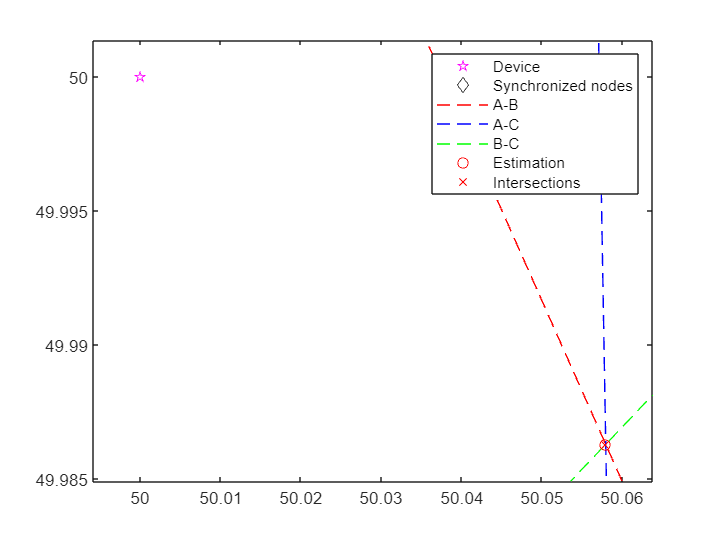

zoomInToEstimationArea(deviceLoc,xC,yC,xO,yO,leg);

The IEEE 802.15.4z localization algorithm allows for multiple intersection points between 2 hyperbolic surfaces, thus either one or two possible localization answers exist. Calculate the localization error for each answer:

for idx = 1:numel(xO)
  locError = sqrt(sum([xO(idx) yO(idx)]-deviceLoc).^2);
  fprintf('Localization error #%d = %0.3f m.\n',idx,locError);
end

Localization error #1 = 0.044 m.


For localization methods that rely on estimating the time of arrival, errors in the distance estimate are primarily caused when the arrival time is not an integer multiple of the sample time. The largest distance error for such localization methods occurs when the arrival time lasts half a sample time more than an integer multiple of sample time. The smallest distance error occurs when the arrival time is an integer multiple of sample time. For the higher pulse repetition frequency (HRPF) mode of the high rate pulse repetition frequency (HRP) PHY used in this example, the symbol rate is 499.2 MHz and the number of samples per symbol is 10. The maximum distance estimation error is $0\ldotp 5\times c/\left(499\ldotp 2\times 10\right)$, which is approximately 3 cm.

In general, the larger channel bandwidth in UWB corresponds to shorter symbol duration and smaller ranging error as compared to narrowband communication. For the narrowband communication as specified in IEEE 802.11az, the channel bandwidth ranges from 20 MHz to 160 MHz. Considering the maximum distance error for narrowband communication, estimates for the localization error lie between 0 and 10 cm for 160 MHz and between 0 and 75 cm for 20 MHz. For more information regarding positioning with IEEE 802.11az, see the [802.11az Positioning Using Super-Resolution Time of Arrival Estimation](docid:wlan_ug#example-HERangingPositioningExample) example.

## Further Exploration

This example uses the following objects and functions:

- [lrwpanHRPConfig](docid:comm_ref#mw_838a7c27-eb97-42fe-bc8e-30a3c0de9f7f): HRP waveform configuration

- [lrwpanWaveformGenerator](docid:comm_ref#mw_9127f1df-f8a2-4131-9dfa-a89604c1bb38): Create an IEEE 802.15.4a/z HRP UWB waveform

- lrwpan.MACFrameConfig: Create configuration for 802.15.4 MAC frames

- lrwpan.MACFrameGenerator: Generate 802.15.4 MAC frames

The API and functionality of undocumented utilities may change in the future. To view the source code of the undocumented utilities, use the [`edit`](docid:matlab_ref#btk4bs6) function.

function zoomInToEstimationArea(deviceLoc,xC,yC,xO,yO,leg)
% Zoom 2D plane into region around device location

  allX = [deviceLoc(1); xO(:); xC(:)];
  allY = [deviceLoc(2); yO(:); yC(:)];
  minX = min(allX);
  maxX = max(allX);
  minY = min(allY);
  maxY = max(allY);
  axis([ ...
      minX-0.1*(maxX-minX), ...
      maxX+0.1*(maxX-minX), ...
      minY-0.1*(maxY-minY), ...
      maxY+0.1*(maxY-minY)])
  leg.Location = 'NorthEast';
end